# **Análisis de Datos (Titanic)**

#  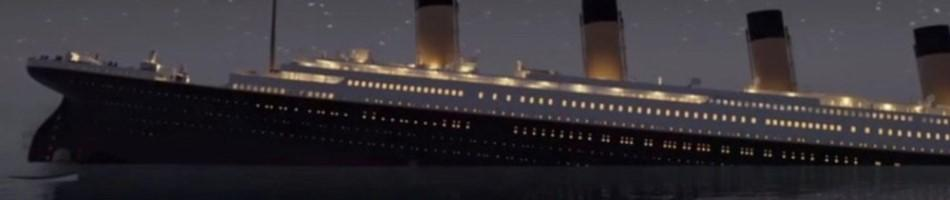  

#  ` ⌛` Paso 1 : Carga de Datos 

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 12);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["PassengerId", "Survived", "Pclass", "Name", "Sex", "Age", "SibSp", "Parch", "Ticket", "Fare", "Cabin", "Embarked"];
opts.VariableTypes = ["double", "double", "double", "string", "categorical", "double", "double", "double", "double", "double", "string", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Name", "Cabin"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Name", "Sex", "Cabin", "Embarked"], "EmptyFieldRule", "auto");

% Import the data
titanic = readtable("C:\Users\MarcoA\Documents\MATLAB\u_sabana_git\titanic_dataset.csv", opts);

% Clear temporary variables
clear opts

% Display results
titanic

titanic = 891×12 table
    PassengerId    Survived    Pclass                            Name                              Sex      Age    SibSp    Parch      Ticket       Fare     Cabin     Embarked
    ___________    ________    ______    _____________________________________________________    ______    ___    _____    _____    __________    ______    ______    ________

         1            0          3       "Braund, Mr. Owen Harris"                                male       22      1        0             NaN      7.25    ""           S    
         2            1          1      

# 🔍Paso 2: Exploración inicial de los datos

% Ver cuántos valores faltantes hay en cada columna
missing = sum(ismissing(titanic)) 

missing =      0     0     0     0     0   177     0     0   230     0     0     2


# 🧹Paso 3 :  Limpieza de los Datos

Sobre el archivo podemos ver

- Tiene un total de 12 columnas como Id del pasajero, sexo, edad, tarifa, cabina, entre otras y 891 filas

- Se tienen 3 tipos de datos Flotantes, Enteros y Strings

- Se tienen una gran cantidad de Missing Values (Nan).

- Columnas como PassengerId, Survived, Pclass, Name, Sex, SibSp, y Parch no tienen valores faltantes

- Las columnas con mayores valores faltantes pueden requeridad imputar los valores faltantes o si no sirven para el análisis excluirlos

# 👴Remover valores NaN sobre Age


titanic = rmmissing(titanic, 'DataVariables', 'Age');
titanic





# **Eliminemos categorias inecesarias:**

titanic = removevars(titanic, {'Cabin', 'Ticket', 'Name', 'PassengerId'})

titanic = 714×8 table
    Survived    Pclass     Sex      Age    SibSp    Parch     Fare     Embarked
    ________    ______    ______    ___    _____    _____    ______    ________

       0          3       male      22       1        0        7.25       S    
       1          1       female    38       1        0      71.283       C    
       1          3       female    26       0        0       7.925       S    
       1          1       female    35       1        0        53.1       S    
       0          3       male      35       0        0        8.05       S    
       0          1       male      54       0        0      51.862       S    
       0          3       male       2       3        1      21.0

grp = groupcounts(titanic,'Survived'); 
figure('Units','inches','Position',[1 1 8 6]); 
bar(grp.Survived,grp.GroupCount); 
set(gca, 'XTick', grp.Survived, 'XTickLabel', {'Not Survived','Survived'}); 

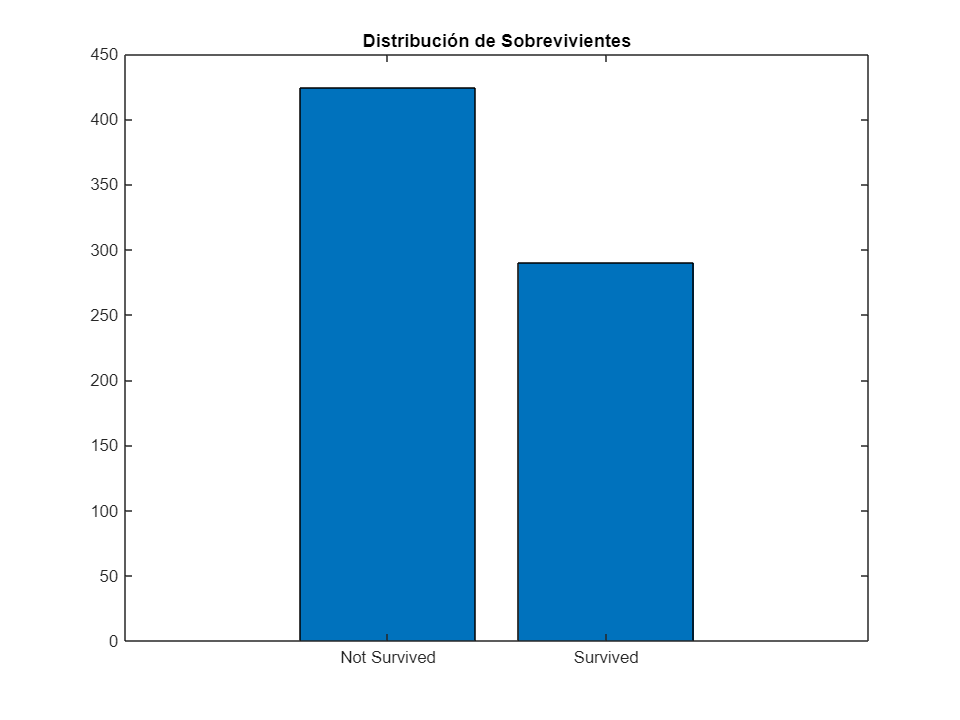

title('Distribución de Sobrevivientes');

stats = groupsummary(titanic, 'Pclass', 'mean', 'Survived');
figure('Units','inches','Position',[1 1 10 6]);
bar(stats.Pclass, stats.mean_Survived);
title('Tasa de supervivencia por clase');
xlabel('Pclass');

                                                                          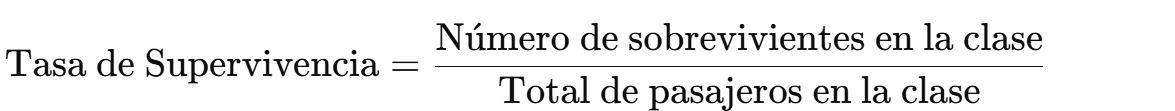

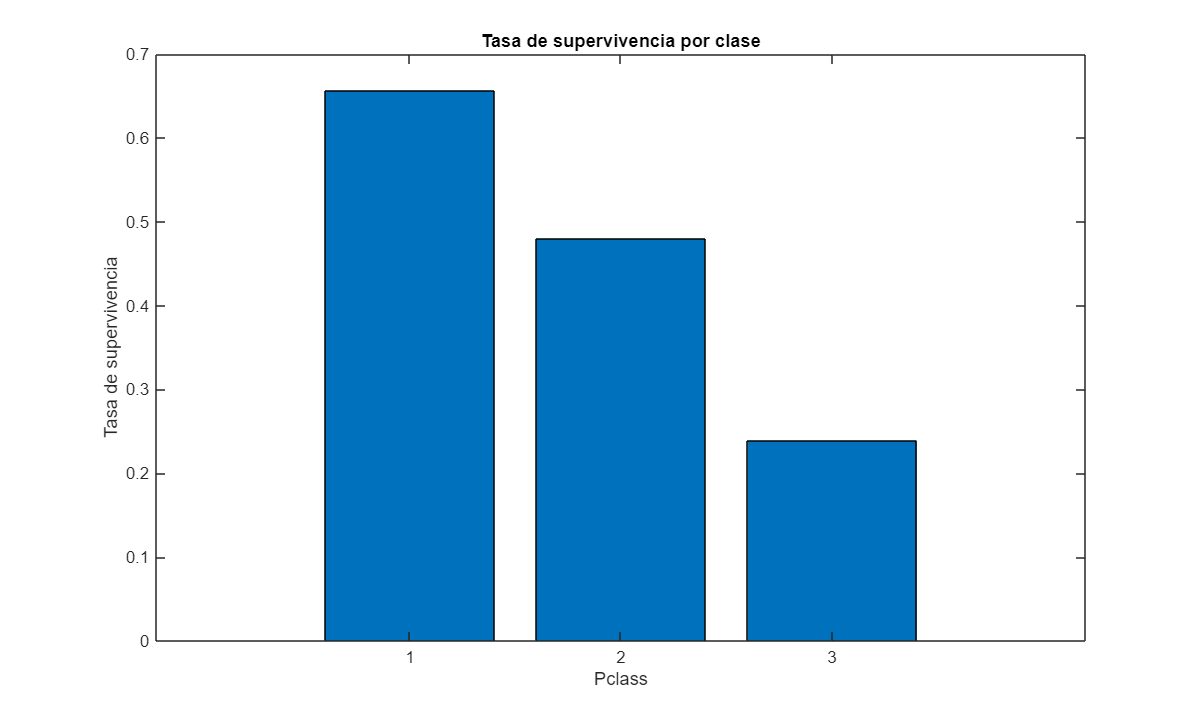

ylabel('Tasa de supervivencia');

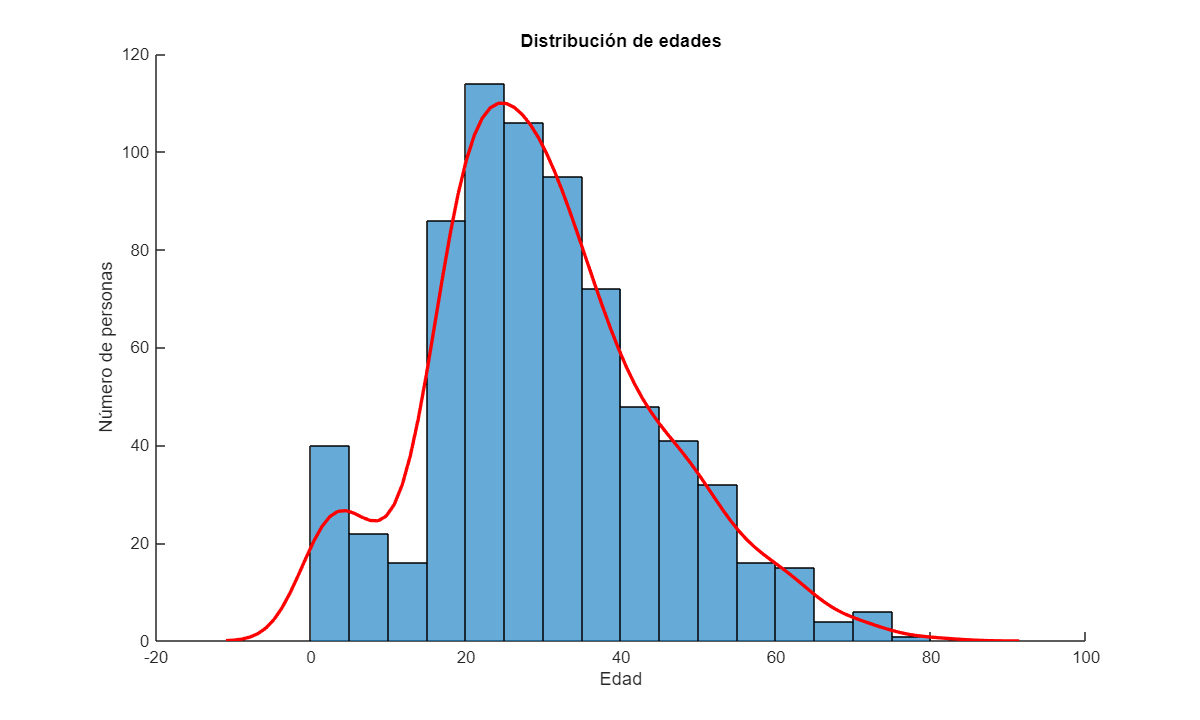

figure('Units', 'inches', 'Position', [1 1 10 6]);
hold on;

% Histograma con conteo
h = histogram(titanic.Age, 'FaceAlpha', 0.6); 
binWidth = h.BinWidth; % Obtener el ancho de los bins
counts = h.Values; % Obtener los conteos del histograma

% Estimación de densidad escalada al número de personas
[f, xi] = ksdensity(titanic.Age);
f = f * sum(counts) * binWidth; % Escalar la densidad al total de cuentas

% Graficar la línea de densidad escalada
plot(xi, f, 'r', 'LineWidth', 2); 

title('Distribución de edades');
xlabel('Edad');
ylabel('Número de personas');

hold off;